**Numerical Methods Midterm Exam 2022 - Solutions**

a. Find and display all **real roots** of the following polynomial to 8 decimal places accuracy.


$$\(p\left(x\right)=2x-5x^2-x^3-2x^7\)$$


% Enter solution here
format long
p= @(x) 2*x-5*x.^2-x.^3-2*x.^7;
dp = @(x) -14*x^6 - 3*x^2 - 10*x + 2;
p_poly = [-2 0 0 0 -1 -5 2 0];
pppp = [];
rr=roots(p_poly);
real_root = [-1.22056809; 0.37136790; 0];
for i = 1:length(rr)
    p(rr(i));
end

disp(real_root)

  -1.220568090000000
   0.371367900000000
                   0



b. Plot the polynomial over an appropriate domain and mark on the real roots with large red circles.

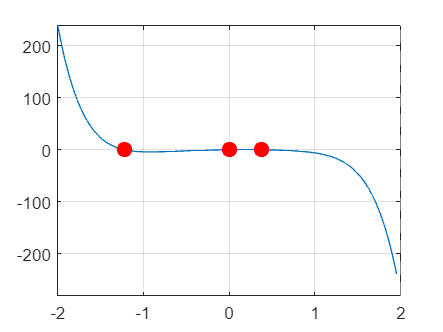

% Enter solution here
fplot(p,[-2,2])
hold on
grid on
plot(0,0,'or','MarkerFaceColor','r','MarkerSize',8)
plot(real_root(1),p(real_root(1)),'or','MarkerFaceColor','r','MarkerSize',8)
plot(real_root(2),p(real_root(2)),'or','MarkerFaceColor','r','MarkerSize',8)
hold off

c. Find the locations of any local extrema of $p(x)$ and plot them with large green diamonds.

% Enter solution here
dp_poly = [-14 0 0 0 -3 -10 2];
drr=roots(dp_poly)

drr =  -0.923343108497221 + 0.000000000000000i
 -0.370924435807010 + 0.872609760507191i
 -0.370924435807010 - 0.872609760507191i
  0.737997428671545 + 0.604116190238826i
  0.737997428671545 - 0.604116190238826i
  0.189197122768149 + 0.000000000000000i


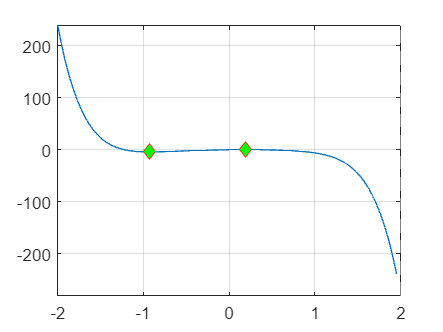


fplot(p,[-2,2])
hold on
grid on
plot(-0.92334311,p(-0.92334311),'or','MarkerFaceColor','g','marker','diamond')
plot(0.18919712,p(0.18919712),'or','MarkerFaceColor','g','marker','diamond')
%
% xlim([-1,1])
hold off

dp(-0.92334311)

ans =     -7.801844148502823e-08


dp(0.18919712)

ans =      3.088021904851246e-08


d. Find the locations of any points of inflections and plot them with large purple stars.

% Enter solution here
ddp = @(x) -84*x^5 - 6*x - 10;
ddrr = [-84 0 0 0 -6 -10];
roots(ddrr)

ans =   0.545390098384078 + 0.429112955221077i
  0.545390098384078 - 0.429112955221077i
 -0.246488124462373 + 0.593930641242215i
 -0.246488124462373 - 0.593930641242215i
 -0.597803947843409 + 0.000000000000000i


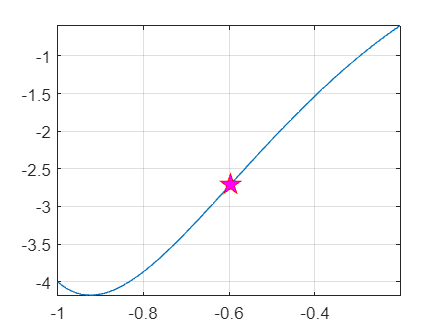


fplot(p,[-2,2])
hold on
grid on
plot(-0.59780395,p(-0.59780395),'or','MarkerFaceColor','m','Marker','pentagram',MarkerSize=12)
xlim([-1,-0.2])
hold off

2.  The speed v of a Saturn V rocket in vertical flight near the surface of earth can be approximated by:

where,

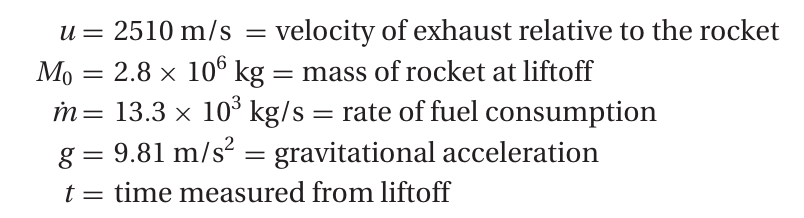

Determine the time when the rocket reaches the speed of sound (335 m/s).

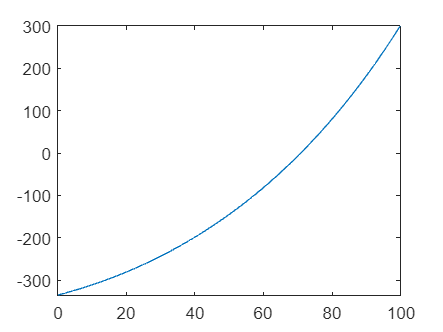

% Enter solution here
v = @(t) 2510*log(2.8.*10.^6./(2.8.*10.^6-13.3.*10.^3.*t))-9.81.*t-335;
%dv = @(t) -(93472400000000*((19*t)./4000 - 1))./(13300*t - 2800000).^2 - 981/100


fplot(v,[0,100])

incsearch_stepsize(v,40,80,0.1)

number of brackets:
     1



ans =   70.799999999999997  70.900000000000006


time_val = bisect(v,70.8,70.9,0.00000001)

time_val =   70.877972030639654



check_val = v(70.877971649169936)

check_val =     -5.052616074863181e-06


3. Find all real solutions to the following system of equations on the domain $-\pi/2 \leq x\leq \pi/2, \,\,\,\, -5 \leq x\leq 5$ to 7 decimal places then create a plot which displays the solution.


$$\tan(2x - 1)=1 + \cos(y) \\
\cos(x)=2\sin^2(y)$$


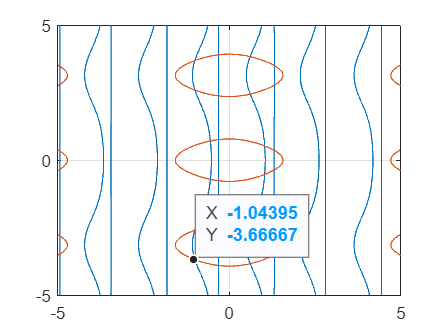

% Enter solution here
z = @(x,y) -1-cos(y)+tan(2*x-1);
z2 = @(x,y) 2*(sin(y)).^2-cos(x);
fimplicit(z,[-5,5])
grid on
hold on
fimplicit(z2,[-5,5])

hold off

4. Three tensile tests were carried out on an aluminium bar. In each test the strain was measured at the same values of stress.

The results were:

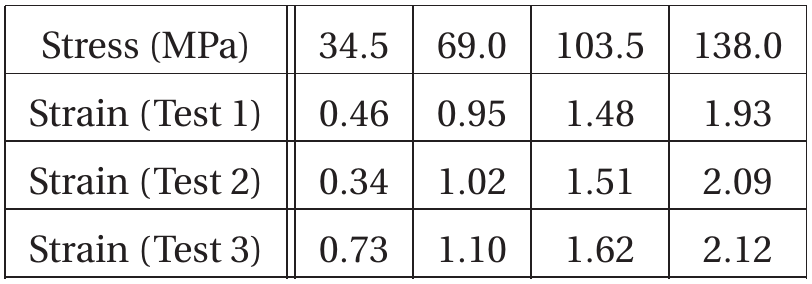

where the units of strain are mm/m ("millimetres per metre"). 

Plot the data then use linear regression to estimate the modulus of elasticity of the bar (modulus of elasticity = stress/strain). Plot the regression line on the same figure as the data.

% Enter solution here


5. The following data is to be fit to a power equation of the form,

$w = Ax^By^Cz^D$,

where A, B, C and D are constants. 

Use linearisation and regression to estimate the values of A. B. C and D then use the fitted power equation to estimate the value of w at the point $(x,y,z) = (3.5, 2.3, 7.1)$.

Data:


$$\matrix{
x & y & z & w \cr
4 & 6 & 8 & 34.68 \cr
1 & 6 & 12 & 9.47 \cr
2 & 10 & 12 & 25.61 \cr
1 & 10 & 6 & 5.97 \cr
1 & 4 & 6 & 4.46 \cr
5 & 7 & 10 & 58.22 \cr
4 & 6 & 15 & 61.07 \cr
2 & 9 & 8 & 17.19 \cr
5 & 9 & 11 & 68.75 \cr
1 & 10 & 7 & 6.86 \cr
}$$


% Enter solution here


6. Consider the following multivariable function:


$$\(f\left(x,y\right)=\frac{10-y}{x-3}\)$$


We wish to evaluate $\(f\left(\frac{1,000,000}{333,333},\frac{5}{7}\right)\)$ in Matlab.

a. What is the true relative error when rounding the $x$ and $y$ values to 6 decimal places in the calculation?

% Enter solution here
format short
f = @(x,y) (10-y)/(x-3);
x_val = 10^6/333333;
y_val = 5/7;
y_round = round(y_val,6)

y_round = 0.7143

x_round = round(x_val,6);

true_val = f(x_val,y_val)

true_val = 3.0952e+06

estimated_val = f(x_round,y_round);
true_relative = abs(true_val-estimated_val)/true_val

true_relative = 9.6917e-07

b. What is the true absolute error when using double precision in the calculation?

% Enter solution here
double_val = f(double(x_val),double(y_val))

double_val = 3.0952e+06

true_absolute = abs(true_val - double_val)

true_absolute = 0

c. To calculate the relative error in part (a) you had to divide a relatively small number by a relatively large number. Can you trust that value or not? Explain/demonstrate why the relative error you calculated can either be trusted or not.

% Enter solution here


 --- FUNCTIONS ---

A space to place your functions so that after running the code blocks below you can then use them in the scripts above.